mystartdefaults
BZpath


Function BZpath: 4 segments
Segment 1: direction [-1 -1 -1]'
Segment 2: direction [1 0 0]'
Segment 3: direction [-1 -1 0]'
Segment 4: direction [-1 -1 0]'
q1         q2         q3         Magnitude       LinearCoord     SegmentID      
0.500      0.500      0.500      0.866           0.000           1              
0.480      0.480      0.480      0.831           0.020           1              
0.460      0.460      0.460      0.797           0.040           1              
0.440      0.440      0.440      0.762           0.060           1              
0.420      0.420      0.420      0.727           0.080           1              
0.400      0.400      0.400      0.693           0.100           1              
0.380      0.380      0.380      0.658           0.120           1              
0.360      0.360      0.360      0.624           0.140           1              
0.340      0.340      0.340      0.589           0.160           1              
0.320      0.320      0.320      0

ans =     0.5000    0.4800    0.4600    0.4400    0.4200    0.4000    0.3800    0.3600    0.3400    0.3200    0.3000    0.2800    0.2600    0.2400    0.2200    0.2000    0.1800    0.1600    0.1400    0.1200    0.1000    0.0800    0.0600    0.0400    0.0200         0         0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600
    0.5000    0.4800    0.4600    0.4400    0.4200    0.4000    0.3800    0.3600    0.3400    0.3200    0.3000    0.2800    0.2600    0.2400    0.2200    0.2000    0.1800    0.1600    0.1400    0.1200    0.1000    0.0800    0.0600    0.0400    0.0200         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

CohenBergstresser1966

recipunit = 1.e+10;
ekinscale = ((hbar*recipunit)^2/(2*elm))/qel;
k_points = ans(1:3,:);

Unit vectors in reciprocal space

g = zeros(4,3);
g(1:3,1) = cross(a(:,2),a(:,3))/cell_volume;
g(1:3,2) = cross(a(:,3),a(:,1))/cell_volume;
g(1:3,3) = cross(a(:,1),a(:,2))/cell_volume;

for i = 1:3
    g(4, i) = dot(g(1:3, i), g(1:3, i));
end
disp(g)

     1    -1     1
     1     1    -1
    -1     1     1
     3     3     3



 Build reciprocal lattice

min_norm = sqrt(min(g(4,:)));
limit = ceil(sqrt(sqrt(cutoff))/min_norm);
nodes = (2 * limit + 1)^3;
G_vectors = zeros(5,nodes);
n = 0;
% Loop to generate G vectors
for h = -limit:limit
    for k = -limit:limit
        for l = -limit:limit
            n=n+1;
            G_vectors(1:3,n) = h * g(1:3,1) + k * g(1:3,2) + l * g(1:3,3);
            G_vectors(5,n) = dot(G_vectors(1:3,n),G_vectors(1:3,n));
            G_vectors(4,n) = sqrt(G_vectors(5,n));
        end
    end
end
disp(G_vectors)

   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000   -4.0000   -3.0000   -2.0000   -1.0000         0   -5.0000   -4.0000   -3.0000   -2.0000   -1.0000   -6.0000   -5.0000   -4.0000   -3.0000   -2.0000   -1.0000         0    1.0000    2.0000    3.0000   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000   -4.0000   -3.0000   -2.0000   -1.0000         0   -5.0000   -4.0000   -3.0000   -2.0000   -1.0000         0    1.0000    2.0000    3.0000    4.0000   -1.0000         0    1.0000    2.0000    3.0000   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000   -4.0000   -3.0000   -2.0000   -1.0000         0    1.0000    2.0000    3.0000    4.0000    5.0000         0    1.0000    2.0000    3.0000    4.0000   -1.0000         0    1.0000    2.0000    3.0000   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000

G = sortrows(G_vectors', 4)';
disp(G)

         0   -1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000    1.0000         0   -2.0000         0         0    2.0000         0   -2.0000         0   -2.0000         0   -2.0000    2.0000   -2.0000    2.0000         0    2.0000         0    2.0000   -1.0000   -3.0000   -1.0000   -3.0000   -1.0000    1.0000    1.0000   -3.0000   -3.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000    3.0000    3.0000   -1.0000   -1.0000    1.0000    3.0000    1.0000    3.0000    1.0000   -2.0000   -2.0000    2.0000   -2.0000    2.0000   -2.0000    2.0000    2.0000         0   -4.0000         0         0    4.0000         0   -1.0000   -3.0000    1.0000   -3.0000    3.0000    3.0000   -3.0000   -3.0000    3.0000   -1.0000    3.0000    1.0000         0   -4.0000    2.0000   -4.0000         0   -2.0000    2.0000         0    4.0000   -2.0000    4.0000         0   -2.0000    2.0000   -4.0000    4.0000   -2.0000    2.0000    1.0000   -5.0000   -1.0000    1.0000    5.0000

Cutoff

num_G_vectors=1;
for n = 2:nodes
    if(G(5,n) <= cutoff)
        num_G_vectors=num_G_vectors + 1;
    end
end

Loops for VG

H = zeros(num_G_vectors, num_G_vectors);
G_diff = zeros(5,1)

G_diff =      0
     0
     0
     0
     0


for n = 1:num_G_vectors
    VG(n) = 0;
    VS = 0;
    VA = 0;
    if G(5,n)==0
        VS = ff(m,1) * Rydberg;
        VA = 0;
    elseif G(5,n) == 3
        VS = ff(m,2) * Rydberg; 
        VA = ff(m,5) * Rydberg;
    elseif G(5,n) == 4
        VS = 0; 
        VA = ff(m,6) * Rydberg;
    elseif G(5,n) == 8
        VS = ff(m,3) * Rydberg; 
        VA = 0;
    elseif G(5,n) == 11
        VS = ff(m,4) * Rydberg; 
        VA = ff(m,7) * Rydberg;
    end
    VG(n) = VS * cos(2 * pi * dot(G(1:3,n),tau(1:3,1))) - 1i * VA * sin(2 * pi * dot(G(1:3,n),tau(1:3,1)));
end

Hamiltonian

for j=1:num_G_vectors
    for i=1:num_G_vectors
        G_diff(1:3) = G(1:3,i) - G(1:3,j);
        G_diff(5) = dot(G_diff(1:3),G_diff(1:3));
        if(G_diff(5) <= Gs_max)
            for k=1:num_G_vectors
                if norm(G_diff(1:3)-G(1:3,k)) < tol
                    H(i,j) = VG(k);
                end
            end
        end
    end 
end
disp(H)

   -9.4573    2.2128   -2.2128   -2.2128   -2.2128   -2.2128   -2.2128   -2.2128    2.2128         0         0         0         0         0         0   -0.1361   -0.1361   -0.1361    0.1361    0.1361    0.1361    0.1361    0.1361    0.1361   -0.1361   -0.1361   -0.1361   -0.5772   -0.5772   -0.5772   -0.5772   -0.5772   -0.5772    0.5772   -0.5772    0.5772    0.5772   -0.5772   -0.5772   -0.5772   -0.5772    0.5772    0.5772   -0.5772    0.5772   -0.5772   -0.5772   -0.5772   -0.5772   -0.5772   -0.5772         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.2128   -9.4573         0         0         0   -0.1361   -0.1361   -0.1361         0   -2.2128   -2.212

Kinetic energy + plotting

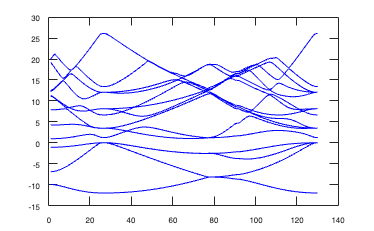

spacing = ls(m);
ekinunit = ekinscale*(2*pi/spacing)^2;
num_k_points = 1:size(k_points,2);
for i = 1:size(k_points,2)
    for j = 1:num_G_vectors
        for k = 1:size(k_points,1)
            p(k)=k_points(k,i) - G(k,j);
        end
        H(j,j) = ekinunit * (dot(p,p)) + VG(1);
    end
    [v,ev]=eig(H);
    E=real(diag(ev));
    [E,perm]=sort(E);
    v=v(:,perm);
    for g=1:nband
        bandstructure(g,i) = E(g);
    end
end

plot(num_k_points,bandstructure,'Color','blue','MarkerSize',2);

disp(bandstructure)

   -9.9651   -9.9874  -10.0415  -10.1224  -10.2238  -10.3396  -10.4644  -10.5940  -10.7249  -10.8547  -10.9813  -11.1035  -11.2199  -11.3299  -11.4326  -11.5276  -11.6144  -11.6928  -11.7625  -11.8232  -11.8748  -11.9172  -11.9503  -11.9740  -11.9882  -11.9930  -11.9930  -11.9914  -11.9866  -11.9787  -11.9677  -11.9534  -11.9361  -11.9155  -11.8918  -11.8650  -11.8351  -11.8020  -11.7658  -11.7264  -11.6840  -11.6385  -11.5898  -11.5381  -11.4834  -11.4256  -11.3647  -11.3009  -11.2340  -11.1641  -11.0913  -11.0155  -10.9367  -10.8550  -10.7705  -10.6831  -10.5928  -10.4997  -10.4038  -10.3051  -10.2036  -10.0995   -9.9927   -9.8832   -9.7711   -9.6564   -9.5391   -9.4194   -9.2971   -9.1725   -9.0454   -8.9160   -8.7843   -8.6503   -8.5141   -8.3757   -8.2352   -8.1791   -8.1846   -8.1947   -8.2105   -8.2316   -8.2583   -8.2908   -8.3299   -8.3759   -8.4296   -8.4912   -8.5611   -8.6394   -8.6818   -8.6818   -8.7725   -8.8711   -8.9769   -9.0892   -9.2070   -9.3294   -9.4555   -9.5842

fasdklfj

%find maximum/ridberg
max(bandstructure(3,:))/Rydberg

ans = 5.3351e-07